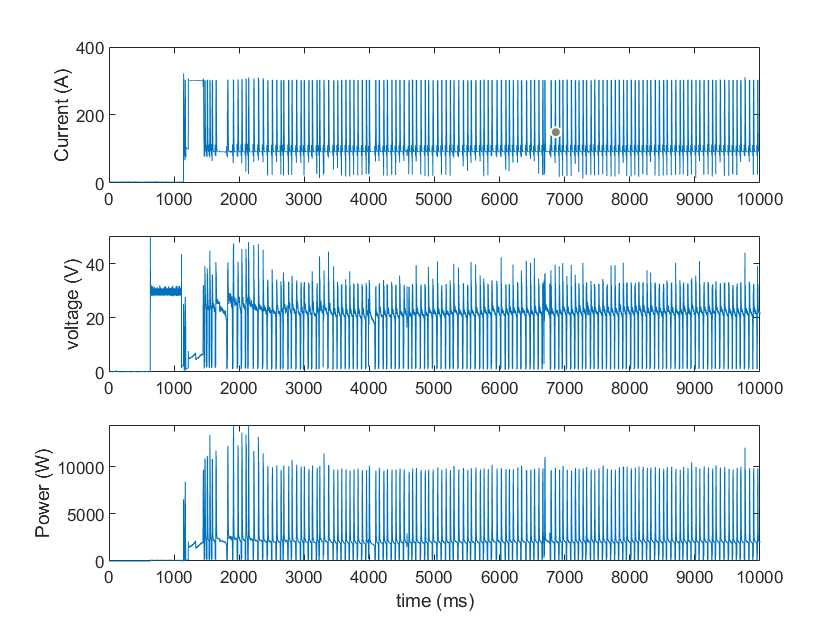

% This code is to plot the values from the oscilloscope
% The data format is CSV
% ----------------------------------------------------------------------

%initialnize
sampleInterval = 0.1;   % The unite is in 'ms'; This value is in 'Sample Interval' in the csv file
CURRENT_AMPLIFICATION = 1000;    % the gain from current Fluck clampmeter

% read CSV file
% load the data from 22 row to the end row, from second column to end colunm
% note the first row and colunm is 0
% osc = csvread('D:\Major Project\Code Project\Wareform Analysis\OSC\CMT\16092020 trial2 voltage.csv',21,1);
osc = csvread('D:\Major Project\Experiment Data\09112020_trial01\03_tek0009ALL.csv',21,1);

% extract the data from the 'osc'
voltageData = osc(:, 1);
currentData = osc(:, 2);

%--------------------------------------------------%
% 取全部采样点用下面algorithm
current = currentData * CURRENT_AMPLIFICATION;
voltage = voltageData;
timeStamp = length(current);
%--------------------------------------------------%

%--------------------------------------------------%
% calculate engergy input
power = current .* voltage;

%--------------------------------------------------%
% 间隔取采样点用下面algorithm
% voltage = [];
% for i=1:2:length(voltageData)
%     voltage = [voltage, voltageData(i,:)];    %累加
% end

% current = [];
% for i=1:2:length(currentData)
%     current = [current, currentData(i,:)];    %累加
% end
% current = current * CURRENT_AMPLIFICATION
% 
% timeStamp = length(current);
%--------------------------------------------------%


% plot
X = (1 : timeStamp) * sampleInterval;
figure
h_sp1 = subplot(3,1,1);
plot(X,current);
ylabel('Current (A)')
h_sp2 = subplot(3,1,2); 
plot(X,voltage);
ylabel('voltage (V)')
h_sp3 = subplot(3,1,3); 
plot(X,power)
ylabel('Power (W)')
xlabel('time (ms)')

linkaxes([h_sp1, h_sp2, h_sp3], 'x');